clear;
clc;
% [filename, pathname] = uigetfile({'*.csv', 'CSV Files (*.csv)'; ...
%                                   '*.*', 'All Files (*.*)'}, ...
%                                   'Select a CSV file');
% fullpath = fullfile(pathname, filename);
% data_noload = readtable(fullpath, 'Range', 'A:B'); 
[filename, pathname] = uigetfile({'*.xls;*.xlsx', 'Excel Files (*.xls, *.xlsx)'; ...
                                  '*.*', 'All Files (*.*)'}, ...
                                  'Select an Excel file');
fullpath = fullfile(pathname, filename);
data_noload = readtable(fullpath, 'Range', 'A:B'); 
dataMatrix = table2array(data_noload);
current = dataMatrix(:,2);
time_expt = dataMatrix(:,1);
% [filename, pathname] = uigetfile({'*.csv', 'CSV Files (*.csv)'; ...
%                                   '*.*', 'All Files (*.*)'}, ...
%                                   'Select a CSV file');
% fullpath = fullfile(pathname, filename);
% data_noload_2 = readtable(fullpath, 'Range', 'A:B'); 
[filename, pathname] = uigetfile({'*.xls;*.xlsx', 'Excel Files (*.xls, *.xlsx)'; ...
                                  '*.*', 'All Files (*.*)'}, ...
                                  'Select an Excel file');
fullpath = fullfile(pathname, filename);
data_noload_2 = readtable(fullpath, 'Range', 'A:B'); 
dataMatrixx = table2array(data_noload_2);
current2 = dataMatrixx(:,2);
time_expt2 = dataMatrixx(:,1);


incr_h = time_expt(3) - time_expt(2);
fs = 1 / incr_h;
N = length(current);
segment_length = 3*N/6;
[Pxx, f] = pwelch(current, segment_length , [], [], fs, 'onesided');
P_at_60Hz = interp1(f, Pxx, 60, 'linear', 'extrap');
PSD_dB_relative = 10 * log10(Pxx/ P_at_60Hz);

% Second dataset calculations
incr_f = time_expt2(3) - time_expt2(2);
fss = 1 / incr_f;
N2 = length(current2);
segment_length = 3*N2/6;

[Pxx2, f2] = pwelch(current2,segment_length , [], [], fss, 'onesided');

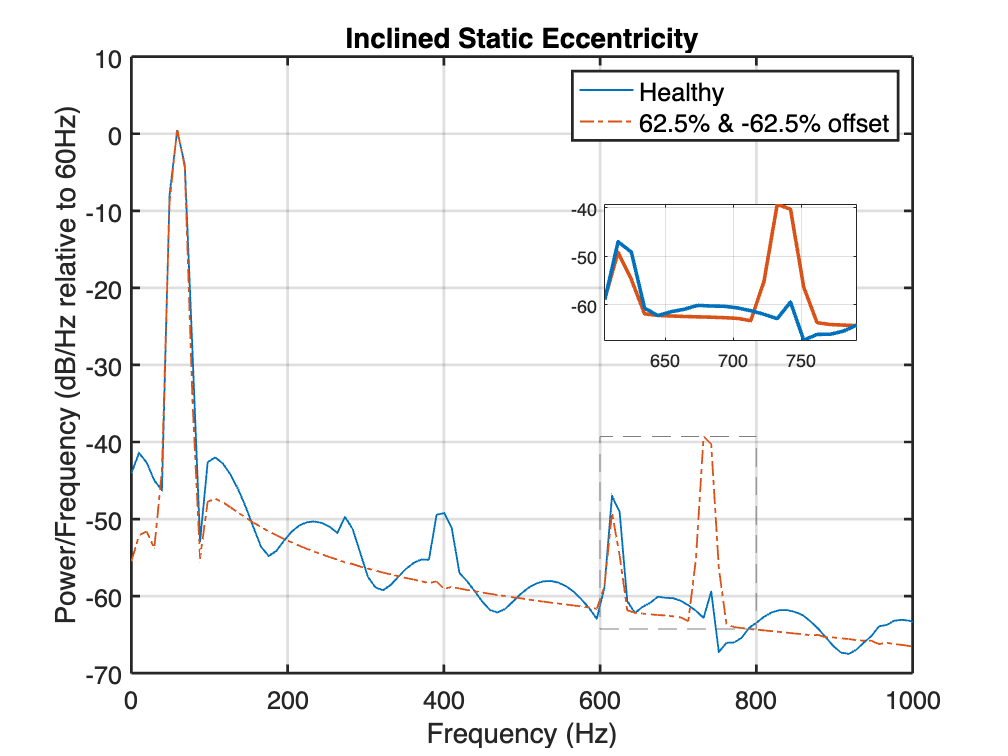

% plot(f2, Pxx2);

P_at_60Hz_2 = interp1(f2, Pxx2, 60, 'linear', 'extrap');
PSD_dB_relative2 = 10 * log10(Pxx2 / P_at_60Hz);

plotPSD(PSD_dB_relative, f, PSD_dB_relative2, f2, true, [600, 800]);

% Compute the FFT of the current
% f_fft = (0:N-1)*(fs/N); % Frequency vector for FFT
% 
% current_fft = fft(current); % Compute FFT
% current_fft_magnitude = abs(current_fft); % Magnitude of the FFT
% 
% Plot the FFT magnitude spectrum
% figure;
% plot(f_fft, current_fft_magnitude,'red'); 
% xlabel('Frequency (Hz)');
% ylabel('Magnitude');
% title('FFT Magnitude Spectrum (Linear Scale)');
% grid on;
% xlim([0 1000]);


% fs = 1/(4e-6);
% 
% % Define window length and overlap
% window_length = length(current)/8; % Example value, can be adjusted
% overlap = window_length/2; % 50% overlap
% nfft = 2^nextpow2(length(current)); % Number of FFT points
% 
% [Pxx, f] = pwelch(current, window_length, overlap, nfft, fs, 'onesided');
% 
% % Find the power at 60Hz
% P_at_60Hz = interp1(f, Pxx, 60, 'linear', 'extrap');
% 
% % Compute the PSD in dB relative to the power at 60Hz
% PSD_dB_relative = 10 * log10(Pxx / P_at_60Hz);
% 
% % Plot the relative PSD in dB
% figure;
% plot(f, PSD_dB_relative);
% xlabel('Frequency (Hz)');
% ylabel('Power/Frequency (dB/Hz relative to 60Hz)');
% title('PSD with 60Hz normalized to 0 dB');
% % grid on;
% xlim([0 1000]);


function plotPSD(PSD_dB_relative, f, PSD_dB_relative2, f2, doZoom, zoomRange)
    if nargin < 6
        zoomRange = [620, 800];
    end
    blue = [0 0.4470 0.7410];
    red = [0.8500 0.3250 0.0980];


    % Plotting
    figure;
    plot(f, PSD_dB_relative, 'Color', blue, 'LineWidth', 1);
    hold on;
    plot(f2, PSD_dB_relative2, 'Color', red, 'LineWidth', 1, 'LineStyle', '-.');
    
    xlabel('Frequency (Hz)', 'FontSize', 15);
    ylabel('Power/Frequency (dB/Hz relative to 60Hz)', 'FontSize', 15);
    set(gca, 'FontSize', 14);
    set(gca, 'LineWidth', 1.5);
    grid on;
    xlim([0 1000]);
    lgd = legend('Healthy', '62.5% & -62.5% offset ');
    title('Inclined Static Eccentricity');
    set(lgd, 'FontSize', 14);

    if doZoom
        % Highlight the zoomed region on the main plot
        indexOfInterest1 = (f > zoomRange(1)) & (f < zoomRange(2));
        indexOfInterest2 = (f2 > zoomRange(1)) & (f2 < zoomRange(2));
        rectangle('Position', [zoomRange(1), min(PSD_dB_relative2(indexOfInterest2)), zoomRange(2)-zoomRange(1), max(PSD_dB_relative2(indexOfInterest2)) - min(PSD_dB_relative2(indexOfInterest2))], 'EdgeColor', [0.5 0.5 0.5], 'LineStyle', '--');

        axes('position', [.60 .55 .25 .18]);
        box on;
        plot(f2(indexOfInterest2), PSD_dB_relative2(indexOfInterest2), 'Color', red, 'LineWidth', 2);
        hold on;
        plot(f(indexOfInterest1), PSD_dB_relative(indexOfInterest1), 'Color', blue, 'LineWidth', 2);
        axis tight;
        grid on;
        hold off;
    end
    hold off;
end

